# Check the gabor filter

% Init
close all; clc

%add path
[curPath, prevPath] = stdnormRootPath();
% path to the function
addpath( genpath( fullfile( curPath, 'functions' )))
addpath( genpath( fullfile( curPath, 'models' )))
addpath( genpath( fullfile( curPath, 'plot_tools' )))

## Check the mean of the current E_ori

dataset = 1;
roi = 2;
model_idx = 3;
E_ori = dataloader( prevPath, 'E_ori', dataset, roi, model_idx, 'old');
mean_E = mean( E_ori(:))

mean_E = 25.3849

This is not good because we want to aovid the accumulation of the pixel value, which may lead to the explosion of the value.

## Check the stimuli

the original data

stimuli_old = dataloader( prevPath, 'stimuli', dataset, roi, model_idx, 'old' );
size( stimuli_old )

ans =    400   400     9    50


mean(stimuli_old(:))

ans = 0.0012

max( stimuli_old(:))

ans = 0.5000

check the resized dataset

stimuli_new = dataloader( prevPath, 'stimuli', dataset, roi, model_idx, 'new' );
size( stimuli_new )

ans =    150   150     9    50


mean(stimuli_new(:))

ans = 0.0012

max(stimuli_new(:))

ans = 0.4991

min( stimuli_new(:))

ans = -0.4974

This means that the input stimuli are normalized to one.

## Check the gabor filter

% get old stimuli
stim_old = stimuli_old( :, :, 1, 1);
mean(abs(stim_old(:)))

ans = 0.0094


filter_cpd  = 3; % the images were band-passed at 3 cycles per degree
fovs        = 12.5 * 1; % deg (the second data set had a larger field of view than the others)
fov         = fovs;
numpix      = size(stim_old,1);
pixperdeg   = numpix / fov;
ppc         = pixperdeg/filter_cpd; % pixels per cycle
support     = 2; % cycles per filter

o = linspace(0,pi, 9);
thetavec = o(1:end-1);

[ Gabor_c1, Gabor_s1]=makeGaborFilter(ppc, thetavec, support);

con_old = squeeze(Icontrast(stim_old, Gabor_c1, Gabor_s1, ppc, thetavec)); %3 - D x , y , theta
max(con_old(:))

ans = 1.2593

min(con_old(:))

ans = 2.3657e-19


% get new stimuli
stim_new = stimuli_new( :, :, 1, 1);
sum(stim_new(:))

ans = 28.6987

filter_cpd  = 3; % the images were band-passed at 3 cycles per degree
fovs        = 12.5 * 1; % deg (the second data set had a larger field of view than the others)
fov         = fovs;
numpix      = size(stim_new,1);
pixperdeg   = numpix / fov;
ppc         = pixperdeg/filter_cpd; % pixels per cycle
support     = 2; % cycles per filter

o = linspace(0,pi, 9);
thetavec = o(1:end-1);

[ Gabor_c, Gabor_s]=makeGaborFilter(ppc, thetavec, support);

con_new = squeeze(Icontrast(stim_new, Gabor_c, Gabor_s, ppc, thetavec)); %3 - D x , y , theta
max(con_new(:))

ans = 0.3907

min(con_new(:))

ans = 1.1083e-20

scalar = mean(con_old(:))/mean(con_new(:))

scalar = 3.1999

This  means during the convolution, the pixel value increase. We need to design another filter.

## check the filter

norm(Gabor_c{1}(:))

Undefined variable Gabor_c.

cn = sqrt(conv2(stim_new, Gabor_c{7}, 'same').^2);
co = sqrt(conv2(stim_old, Gabor_c1{7}, 'same').^2);
mean(co(:))/mean(cn(:))


dataset = 1;
roi = 2;
model_idx = 3;
E_ori = dataloader( prevPath, 'E_ori', dataset, roi, model_idx, 'new');
BOLD_target = dataloader( prevPath, 'BOLD_target', dataset, roi );
model_std = normStdModel( 40 );
[loss, BOLD_pred_std, params_std, Rsquare_std, model_std] = model_std.fit( model_std, E_ori, BOLD_target, 'off', 'cross_valid' );

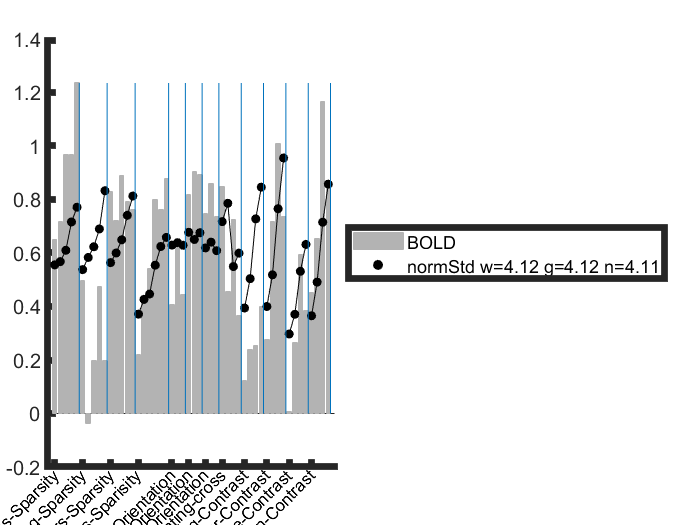

figure;
plot_BOLD( BOLD_pred_std', BOLD_target, dataset, roi, {'BOLD',model_std.legend})